# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.6 Stripmap Signal-to-Noise Ratio

## Calculate the signal-to-noise ratio 

$\textrm{SNR}=\frac{P_{\textrm{avg}} \;A_e^2 \;\sigma \;}{8\pi \;\lambda \;r^3 \;\delta_{a\;} v\;k\;T_0 \;F\;L}$    Equation (2.24)

% Clear the workspace
clear

% Cross-range resolution (m)
cross_range_resolution = 15;

% Radar cross section (m^2)
rcs = [0.05, 1, 10];

% Average transmitted power (W)
average_power = 100;

% Antenna effective aperture (m^2)
effective_aperture = 5;

% Operating frequency (Hz)
operating_frequency = 10e9; 

% Slant range (m)
slant_range = 175e3;

% System temperature (K)
system_temperature = 290;

% Noise figure
noise_figure = lin(6);

% Losses
losses = lin(9);

% Velocity (m/s)
velocity = linspace(50, 500, 1e3);

% Calculate the clutter-to-noise ratio
for i = 1:length(rcs)
snr(i,:) = stripmap_snr(average_power, effective_aperture, rcs(i), cross_range_resolution, ...
    operating_frequency, slant_range, velocity, system_temperature, noise_figure, losses);
end

## Plot the results

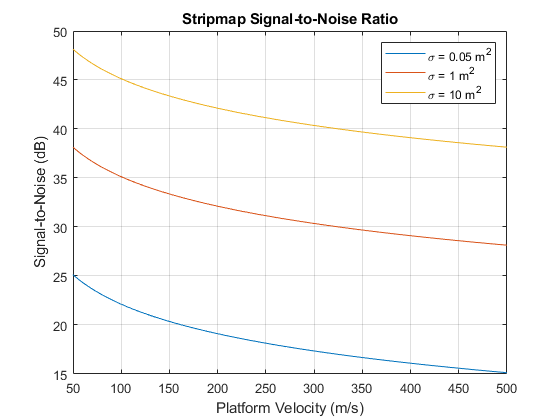

figure;
plot(velocity, db(snr));
xlabel('Platform Velocity (m/s)')
ylabel('Signal-to-Noise (dB)');
title('Stripmap Signal-to-Noise Ratio')
grid on
legend('\sigma = 0.05 m^2', '\sigma = 1 m^2', '\sigma = 10 m^2')